imagesize = [480 640 3];
numClasses = 5;
name = 'EncoderDepth';
% value should be teh depth of the encoder-decoder
the_output_of_unelayers = unetLayers(imagesize,numClasses,name,3)

the_output_of_unelayers =   LayerGraph with properties:

         Layers: [46×1 nnet.cnn.layer.Layer]
    Connections: [48×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


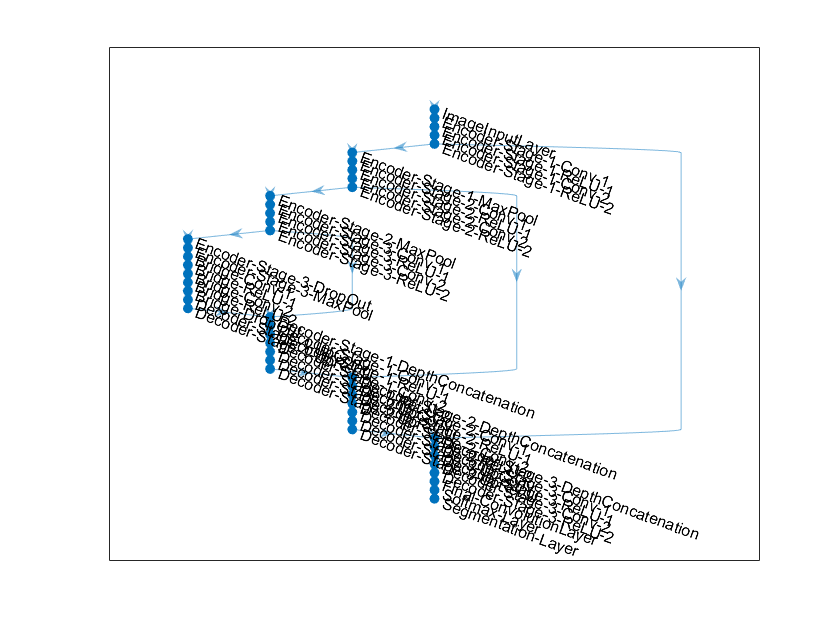

plot(the_output_of_unelayers)


dataSetDir = fullfile(toolboxdir('vision'),'visiondata','triangleImages');
imageDir = fullfile(dataSetDir,'trainingImages');
labelDir = fullfile(dataSetDir,'trainingLabels');
classNames = ["triangle","background"];
labelIDs = [255 0];

imds = imageDatastore(imageDir); 
pxds = pixelLabelDatastore(labelDir,classNames,labelIDs);
u2=unetLayers(imagesize,numClasses);
ds=combine(imds,pxds);
options = trainingOptions('sgdm','InitialLearnRate',1e-3,'MaxEpochs',80,'VerboseFrequency',10);
net = trainNetwork(ds,u2,options)

Error using trainNetwork (line 184)
The training images are of size 32×32×1 but the input layer expects images of size 480×640×3.